# [Solutions] Contraction of finite PEPS

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for the MPO-MPS method of PEPS contraction

The complete version is uploaded as `PEPS/contact_finPEPS.m`. Compare with your versin!

## Solution to Exercise (b): Spin-spin correlation function of the RVB state with different lattice sizes

We consider different sizes of almost-square-shaped lattice, $N_\mathrm{row}$ = (11:2:25) and $N_\mathrm{col} = N_\mathrm{row} \pm 1$, and different maximum bond dimensiosn $N_\mathrm{keep}$ = (20:10:40).

clear

Nrow = (11:2:25);
Nkeep = (20:10:40);
Nsweep = 5;

% define a PEPS tensor and reduced tensors
VB = blkdiag([0,1;-1,0],1);
[S,I] = getLocalSpace('Spin',1/2);
P = zeros(3,3,2,3,3);
for it1 = (1:size(I,2))
    P(it1,3,it1,3,3) = 1;
    P(3,it1,it1,3,3) = 1;
    P(3,3,it1,it1,3) = 1;
    P(3,3,it1,3,it1) = 1;
end
M = contract(P,5,4,VB,2,1);
M = contract(M,5,4,VB,2,1);
MM = contract(conj(M),5,3,M,5,3);
for itl = (1:4)
    MM = contract(MM,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MM,1,MM,5-(itl-1)),3,[1 2]);
end
MSM = contract(conj(M),5,3,S(:,:,2),2,1);
MSM = contract(MSM,5,5,M,5,3);
for itl = (1:4)
    MSM = contract(MSM,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MSM,1,MSM,5-(itl-1)),3,[1 2]);
end

% result array
SzSzval = zeros(numel(Nrow),2,numel(Nkeep));

for it1 = (1:numel(Nrow))
    for it2 = (1:2)
        if it2 == 1
            Ncol = Nrow(it1)-1;
        else
            Ncol = Nrow(it1)+1;
        end

        % network of reduced tensors for the denominator (norm)
        Tden = cell(Nrow(it1),Ncol);
        Tden(:) = {MM};
        Tden(:,1) = cellfun(@(x) x(end,:,:,:), Tden(:,1), 'UniformOutput',false);
        Tden(1,:) = cellfun(@(x) x(:,end,:,:), Tden(1,:), 'UniformOutput',false);
        Tden(end,:) = cellfun(@(x) x(:,:,end,:), Tden(end,:), 'UniformOutput',false);
        Tden(:,end) = cellfun(@(x) x(:,:,:,end), Tden(:,end), 'UniformOutput',false);

        % network of reduced tensors for the numerator (< S S >)
        Tnum = Tden;
        Tnum((end+1)/2,(end/2)+[0 1]) = {MSM};

        for it3 = (1:numel(Nkeep))
            SzSzval(it1,it2,it3) = ...
                contract_finPEPS(Tnum,Nkeep(it3),Nsweep)/ ...
                contract_finPEPS(Tden,Nkeep(it3),Nsweep);
        end
    end
end

We suppress the log message since it's too long.

We plot the result.

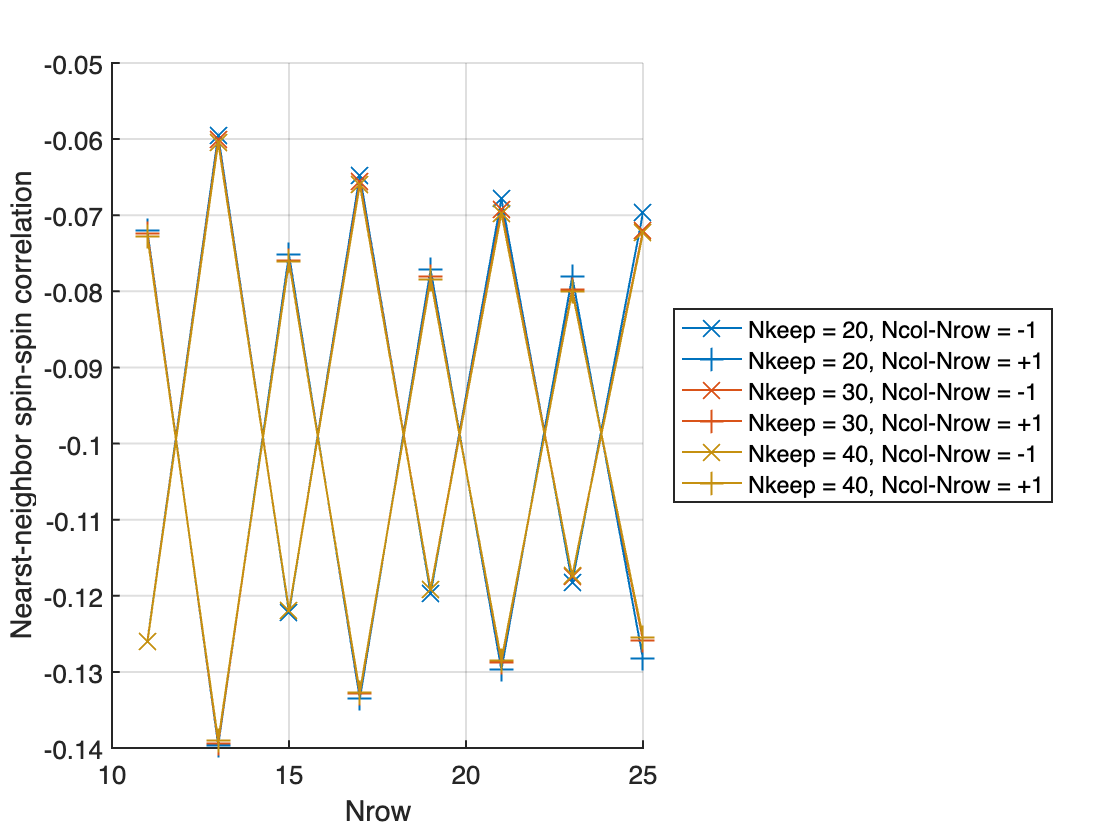

% line colors
clrs = [0 .447 .741; .85 .325 .098; .773 .565 .061];
% markers
mkrs = {'x','+'};

legs = cell(2,numel(Nkeep));

figure;

figure;
hold on;
for it3 = (1:numel(Nkeep))
    for it2 = (1:2)
        plot(Nrow,SzSzval(:,it2,it3),'LineWidth',1, ...
            'LineStyle','-','Marker',mkrs{it2},'MarkerSize',12, ...
            'Color',clrs(it3,:));
        legs{it2,it3} = ['Nkeep = ',sprintf('%i',Nkeep(it3))];
        if it2 == 1
            legs{it2,it3} = [legs{it2,it3},', Ncol-Nrow = -1'];
        else
            legs{it2,it3} = [legs{it2,it3},', Ncol-Nrow = +1'];
        end
    end
end
hold off;
set(gca,'LineWidth',1,'FontSize',13);
grid on;
xlabel('Nrow');
ylabel('Nearst-neighbor spin-spin correlation');
legend(legs(:),'Location','eastoutside');

We see that there are oscillations that depend on the parity of $(N_\mathrm{row} - 1)/2$ and the sign of $N_\mathrm{col} - N_\mathrm{row}$. Such oscillations decay slowly as the system size increases. And the difference in data between different $N_\mathrm{keep}$'s becomes larger for larger system sizes.

How can we get the value in the thermodynamic limit? There may be more sophisticated extrapolation schemes, but here we use very simple-minded approach, which surprisingly (or not) works well. Let's perform the linear regression of all the data points as a function of $1/N_\mathrm{row}$.

xs = 1./Nrow(:) + [0 0];
ys = SzSzval(:,:,end);
p = polyfit(xs(:),ys(:),1);
disp(p(2));

   -0.0982



This result is indeed consistent with a Monte Carlo result, $\langle \hat{S}_{(i,j)}^z \hat{S}_{(i,j+1)}^z \rangle \simeq -0.0987$, obtained in [[A. F. Albuquerque and F. Alet, Phys. Rev. B **82**, 180408(R) (2010)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.82.180408)].

## Solution to Exercise (c): Ground state of Kitaev's toric code

We construct the PEPS tensors that descript the ground state of the toric code on a finite lattice with open boundary conditions. We first define the tensors in the bulk, i.e., away from the boundary. As explained in the lecture, the PEPS representation of the ground state consists of the rank-3 tensors sitting on the edges (with one physical leg onto a spin-1/2 and two bond legs) and the rank-4 tensors at the vertices (all bond legs). We choose the bond space basis such that the first (second) basis state is for $+$ ($-$) spin state.

Let's create the edge tensor whose legs are ordered as left (incoming) - right (outgoing) - physical (incoming) for horizontal edges and up (incoming) - down (outgoing) - physical (incoming) for vertical edges. (Of course, here the notion of leg directions is merely for bookkeeping.)

clear

[S,I] = getLocalSpace('Spin',1/2);

PE = zeros(2,2,2);
PE(1,1,:) = reshape([+1,+1]/sqrt(2),[1 1 2]); % + state
PE(2,2,:) = reshape([+1,-1]/sqrt(2),[1 1 2]); % - state

And we construct the vertex tensor whose legs are ordered as left (incoming) - up (incoming) - down (outgoing) - right (outgoing). We can define the tensor's elements by computing the parity of the number of $-$ states.

PV = (mod([0;1] + [0,1] + reshape([0,1],[1 1 2]) ...
    + reshape([0,1],[1 1 1 2]),2) == 0);

A tensor for a one-site unit cell consists of one vertex tensor and two edge tensors. Here we associate the tensors for the right and down edges with a vertex, so that the unit-cell tensor covers all the lattice sites except for the right and bottom boundaries.

M = contract(PV,4,3,PE,3,1);
M = contract(M,5,3,PE,3,1,[1 2 4 6 3 5]);

The resulting tensor is rank-6, with legs ordered as left (incoming) - up (outgoing) - physical (incoming; for the down edge) - physical (incoming; for the right edge) - down (outgoing) - right (outgoing).

The reduced tensors, with or without $\hat{S}_z$, are given by:

MM = contract(conj(M),6,[3 4],M,6,[3 4]);
% spin-z at the down edge
MzrM = contract(conj(M),6,3,S(:,:,2),2,1);
MzrM = contract(MzrM,6,[3 6],M,6,[4 3]);
% spin-z at the right edge
MzdM = contract(conj(M),6,4,S(:,:,2),2,1);
MzdM = contract(MzdM,6,[3 6],M,6,[3 4]);

% merge bond legs
for itl = (1:4)
    MM = contract(MM,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MM,1,MM,5-(itl-1)),3,[1 2]);
    MzrM = contract(MzrM,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MzrM,1,MzrM,5-(itl-1)),3,[1 2]);
    MzdM = contract(MzdM,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MzdM,1,MzdM,5-(itl-1)),3,[1 2]);
end

For the tensors on the boundary, we project the leg of the vertex tensor `PV`, heading towards the boundary, onto the first basis (i.e., $+$ state). And do not contract the edge tensors with the projected legs. We also don't acting $\hat{S}_z$'s onto those boundary tensors.

We define the tensors on the right and bottom boundaries first. The projections for the left and up legs can be made easily, when we define a network of reduced tensors, as I will show below.

% on the right boundary, away from the bottom boundary
Mr = contract(PV(:,:,:,1),4,3,PE,3,1,[1 2 5 4 3]);
MMr = contract(conj(Mr),5,3,Mr,5,3);
% on the bottom boundary, away from the right boundary
Md = contract(PV(:,:,1,:),4,4,PE,3,1,[1 2 5 3 4]);
MMd = contract(conj(Md),5,3,Md,5,3);
% on the bottom-right corner
Mrd = PV(:,:,1,1);
MMrd = contract(conj(Mrd),5,5,Mrd,5,5);

% merge bond legs
for itl = (1:4)
    MMr = contract(MMr,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MMr,1,MMr,5-(itl-1)),3,[1 2]);
    MMd = contract(MMd,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MMd,1,MMd,5-(itl-1)),3,[1 2]);
    MMrd = contract(MMrd,8-(itl-1),[1 5-(itl-1)], ...
        getIdentity(MMrd,1,MMrd,5-(itl-1)),3,[1 2]);
end

As a demonstration, we choose the following parameters.

Nrow = 10;
Ncol = 10;
Nkeep = 30;
Nsweep = 5;

The network of the reduced tensors that represents the norm square (or the denominator) is given by:

Tden = cell(Nrow,Ncol);
Tden(:) = {MM};
Tden(:,end) = {MMr};
Tden(end,:) = {MMd};
Tden(end,end) = {MMrd};
% project the legs towards the left and top boundaries
Tden(1,:) = cellfun(@(x) x(:,1,:,:), Tden(1,:), 'UniformOutput', false);
Tden(:,1) = cellfun(@(x) x(1,:,:,:), Tden(:,1), 'UniformOutput', false);

Tden_val = contract_finPEPS(Tden,Nkeep,Nsweep);

22-11-15 11:13:23 | Contract tensors on a 10 x 10 lattice, with Nkeep = 30
Elapsed time: 0.391s, CPU time: 0.96s, Avg # of cores: 2.455


disp(Tden_val);

   2.4179e+24



Let's consider a situation that there are $\hat{S}_z$ operators on the edge connecting (4,5) and (5,5) and the edge connecting (6,6) and (6,7).

Tnum = Tden;
Tnum{4,5} = MzdM;
Tnum{6,6} = MzrM;

Tnum_val = contract_finPEPS(Tnum,Nkeep,Nsweep);

22-11-15 11:13:23 | Contract tensors on a 10 x 10 lattice, with Nkeep = 30
Elapsed time: 0.3397s, CPU time: 0.93s, Avg # of cores: 2.738


disp(Tnum_val);

   9.1835e-41



disp(Tnum_val/Tden_val);

   3.7982e-65



The value is zero, being much smaller than the numerical precision. Why? A pair of $\hat{S}_z$ operators creates a pair of "electric charge" excitations; so the application of the $\hat{S}_z$ operators to the ground state yields an excited state. Recall that the ground and excited states can be characterized by different eigenvalues of the star and plaquette terms, which are good quantum numbers. That is, the excited state generated by acting spin operators is orthogonal to the ground state, leading to the vanishing expectation value. This argument applies not only to $\hat{S}_z$ operators, but also to $\hat{S}_x$ operators, as the latter create "magnetic vortices."